# Estabilización del péndulo invertido

Vamos a seguir la sección 10.1 de las notas de clase "How to stabilize a point of a non-linear system".

clear all;
close all;
clc;

## Paso 1

Empezamos escribiendo el modelo del sistema


$$\frac{\mathrm{d}}{\mathrm{dt}} \left[\matrix{\theta \cr \dot\theta}\right] = \left[\matrix{\dot\theta \cr \frac{1}{ml^2} (mgl\sin\theta -b\dot\theta + T) }\right]$$


y escojo el punto $x^* = \left[\matrix{0 \cr 0}\right]$para estabilizar. Eso me lleva a que la entrada ha de ser $u^* = T^* = 0$ para que $x^*$ sea un punto de equilibrio.

## Paso 2

Linearizamos el sismema no lineal en torno a $x^*$ y $u^*$. 

$A = \left[\matrix{0 & 1 \cr \frac{g}{l} & -\frac{b}{ml^2}} \right]$,$B = \left[\matrix{0 \cr 1} \right]$,$C = \left[\matrix{1 & 0} \right]$, and $D = 0$. 

Hemos asumido que solo podemos medir el ángulo $\theta$para el cálculo de C.

Vamos a asumir que $g = 9.8$m/s², $l = 1$m, $m=1$Kg y $b = 0.1$kg m² / s. 

A = [0 1; 9.8 -0.1];
B = [0;1];
C = [1 0];
D = 0;

## Paso 3

Test de controlabilidad (Theorem 6) examinando el rango de la matriz de controlabilidad $\mathcal{C} = \left[\matrix{B & AB}\right]$

Ccon = [B A*B] % También puedes calcularla con el comando ctrb(A,B)

Ccon =                    0   1.000000000000000
   1.000000000000000  -0.100000000000000


rank(Ccon) % El rango es 2 = n, así que el sistema es controlable.

ans =      2


Test de controlabilidad (Theorem 7) examimando que los vectores propios de $A^T$ no pertenecen al kernel de $B^T$.

[eigvectorsAt, eigvaluesAt] = eig(A'); % Aqui ya podemos ver que A no es una 'stability matrix'
B' * eigvectorsAt % Vemos que no sale ningun cero

ans =    0.299905836856846   0.308725647546444


Recordad que el test para ver si un sistema es estabilizable se haría de forma similar a la expresión anterior pero solo mirando los autovectores correspondientes a los autovalores no estables de $A^T$.

## Paso 4

El jacobiano $C$no es cuadrado, por lo que no tiene inversa. Tendremos que diseñar un "observer".

## Paso 5

Test de observabilidad. Hacemos el test de controlabilidad al sistema dual.

Ccondual = [C' A'*C'] % Como antes, tambien podemos usar el comando ctrb(A',C')

Ccondual =      1     0
     0     1


rank(Ccondual) % El rango es igual a n, por lo que es observable

ans =      2


En caso de que no fuera observable, habría que ver si es detectable analizando si el sistema dual es estabilizable  (Theorem 7)

## Paso 6

Para construir el estimador/observador necesitamos diseñar la matriz de ganancias $L$. Como el sistema es observable, podemos poner lo autovalores de $(A-LC)$ donde queramos. En vez de hacerlo a mano (calculando el polinomio característico), lo podemos hacer con los comandos "place" o "acker". Leed el help de place, porque está diseñado para diseñar $K$en $(A-BK)$. Por lo que para $L$ vamos al sistema dual.

Selecciono los autovalores deseados como $-10$ y $-15$.

eigde = [-10 -15];
Kdual = place(A',C',eigde);
L = Kdual'

L = 	1.0e+02 *

   0.249000000000002
   1.573100000000017


eig(A - L*C) % Comprobamos que en efecto los autovaloes estan donde queremos

ans =  -15.000000000000115
 -10.000000000000034


## Paso 7

Si el sistema solamente fuera detectable, no podemos poner los autovalores donde queramos, ya que no tenemos "control" sobre los "autovectores\autovalores estables" de $A$ mediante $LC$. Así que los comandos "place" o "acker" no nos valen. Tendríamos que resolver la ecuación de Lyapunov $AP + PA^T - BB^T < 0$ para el **sistema dual** y así obtener la $K$($L^T$) del sistema dual como $\frac{1}{2}B^TP^{-1}$. La ecuación es una LMI (Linear Matrix Inequality) y se puede resolver numéricamente con herramientas de la Robust Control Toolbox. La ecuación **NO** se resuelve con el comando "lyap".

## Paso 8

Vamos a encontrar la matriz de ganancias $K$tal que $(A-BK)$sea una "stability matrix". De hecho, el sistema es controlable, por lo que podemos asignar los autovalores de $(A-BK)$donde queramos con el comando "place".

Vamos a asignar los autovalores $-3$ y $-5$.

eigde = [-3 -5];
K = place(A,B,eigde)

K =   24.799999999999997   7.899999999999999


eig(A-B*K) % Comprobamos que en efecto los autovalores son los diseñados

ans =   -3.000000000000001
  -4.999999999999997


## Paso 9

Igual comentario que en el Paso 7 para sistemas que son estabilizables pero no controlables.

## Paso 10

Vamos a simular nuestro pendulo invertido con la señal de control $u = -K\hat x$

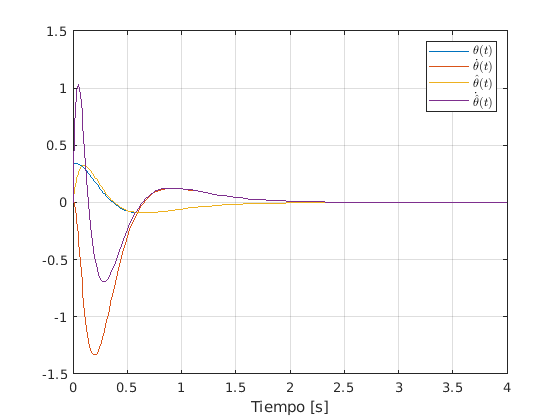

% En pendulo_estimador.m estan los calculos para las derivadas temporales
% del sistema y del estimador.

% Cogemos como condiciones iniciales 0.34rads y 0 rads/sec para thetha y
% dot_theta. Las condiciones iniciales para el estimador son 0 y 0.
[t,x] = ode45(@pendulo_estimador,[0, 4], [0.17*2, 0, 0 , 0]);

figure(1)
plot(t, x(:,1))
hold on
grid on
plot(t, x(:,2))
plot(t, x(:,3))
plot(t, x(:,4))
legend('$\theta (t)$','$\dot\theta (t)$','$\hat\theta (t)$','$\dot{\hat\theta} (t)$','Interpreter','latex')
xlabel('Tiempo [s]')

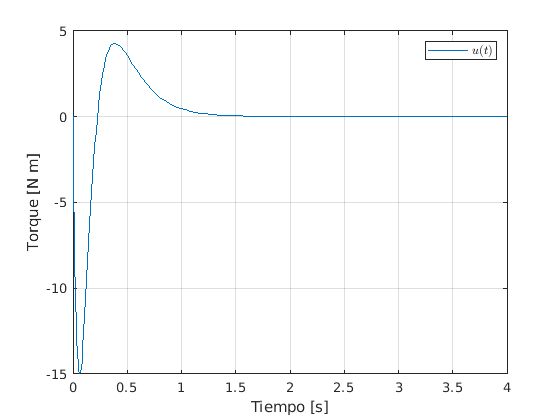


figure(2)
plot(t, -K*x(:,3:4)') % Pintamos la senal de control (torque) aplicada, u = -K*xhat
legend('$u(t)$','Interpreter','latex')
xlabel('Tiempo [s]')
ylabel('Torque [N m]')
grid on

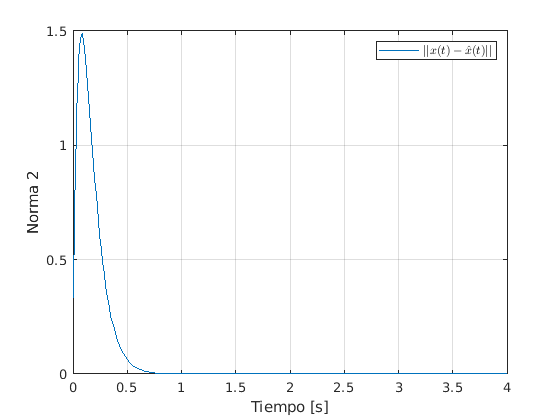

figure(3)
plot(t, vecnorm(x(:,1:2)' - x(:,3:4)'))
legend('$||x(t) - \hat x(t)||$','Interpreter','latex')
xlabel('Tiempo [s]')
ylabel('Norma 2')
grid on